## Condiciones iniciales de arfada

clear
syms a1(t) a2(t) a3(t) a4(t) a5(t)  T_z A
syms v1(t) v2(t) v3(t) v4(t) v5(t)  
syms x1(t) x2(t) x3(t) x4(t) x5(t) 
assume(T_z>0)
assume(A>0)
g=9.81;

%syms g
xMax=0.1

xMax = 0.1000

aMax=g/5

aMax = 1.9620

A=aMax;


## Aceleración

a1(t)=10*A/T_z*t;
a2(t)=A;
a3(t)=-10*A/T_z*t;
Ca3=A-a3(4*T_z/10);
a3(t)=a3(t)+Ca3;
a4(t)=-A;
a5(t)=10*A/T_z*t;
Ca5=a4(9*T_z/10)-a5(9*T_z/10);
a5(t)=a5(t)+Ca5;
fprintf('Función de aceleración:')

Función de aceleración:

a(t)=piecewise((0<=t<T_z/10),a1,(T_z/10<=t<4*T_z/10),a2,(4*T_z/10<=t<6*T_z/10),a3,(6*T_z/10<=t<9*T_z/10),a4,(9*T_z/10<=t<=T_z),a5)

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T_{z}\wedge 0\leq t\\ \frac{981}{500} & \text{ if }T_{z}\leq 10\,t\wedge 5\,t<2\,T_{z}\\ \frac{981}{100}-\sigma_{1} & \text{ if }5\,t<3\,T_{z}\wedge 2\,T_{z}\leq 5\,t\\ -\frac{981}{500} & \text{ if }10\,t<9\,T_{z}\wedge 3\,T_{z}\leq 5\,t\\ \sigma_{1}-\frac{981}{50} & \text{ if }t\leq T_{z}\wedge 9\,T_{z}\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,t}{50\,T_{z}} \end{array}$$

## Velocidad


v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T_z/10)-v2(T_z/10);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(4*T_z/10)-v3(4*T_z/10);
v3(t)=v3(t)+Cv3;

v4(t)=int(a4);
Cv4=v3(6*T_z/10)-v4(6*T_z/10);
v4(t)=v4(t)+Cv4;

v5(t)=int(a5);
Cv5=v4(9*T_z/10)-v5(9*T_z/10);
v5(t)=v5(t)+Cv5;

fprintf('Función de velocidad:')

Función de velocidad:

v(t)=piecewise((0<=t<T_z/10),v1,(T_z/10<=t<4*T_z/10),v2,(4*T_z/10<=t<6*T_z/10),v3,(6*T_z/10<=t<9*T_z/10),v4,(9*T_z/10<=t<=T_z),v5)

$$v(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{100\,T_{z}} & \text{ if }10\,t<T_{z}\wedge 0\leq t\\ \frac{981\,t}{500}-\frac{981\,T_{z}}{10000} & \text{ if }T_{z}\leq 10\,t\wedge 5\,t<2\,T_{z}\\ -\frac{16677\,T_{z}}{10000}-\frac{t\,\left(\frac{981\,t}{T_{z}}-981\right)}{100} & \text{ if }5\,t<3\,T_{z}\wedge 2\,T_{z}\leq 5\,t\\ \frac{18639\,T_{z}}{10000}-\frac{981\,t}{500} & \text{ if }10\,t<9\,T_{z}\wedge 3\,T_{z}\leq 5\,t\\ \frac{981\,T_{z}}{100}+\frac{t\,\left(\frac{981\,t}{2\,T_{z}}-981\right)}{50} & \text{ if }t\leq T_{z}\wedge 9\,T_{z}\leq 10\,t \end{array}\right.$$

## Desplazamiento


z1(t)=int(v1);

z2(t)=int(v2);
Cz2=z1(T_z/10)-z2(T_z/10);
z2(t)=z2(t)+Cz2;

z3(t)=int(v3);
Cz3=z2(4*T_z/10)-z3(4*T_z/10);
z3(t)=z3(t)+Cz3;

z4(t)=int(v4);
Cz4=z3(6*T_z/10)-z4(6*T_z/10);
z4(t)=z4(t)+Cz4;

z5(t)=int(v5);
Cz5=z4(9*T_z/10)-z5(9*T_z/10);
z5(t)=z5(t)+Cz5;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

Fz_arfada(t)=piecewise((0<=t<T_z/10),z1,(T_z/10<=t<4*T_z/10),z2,(4*T_z/10<=t<6*T_z/10),z3,(6*T_z/10<=t<9*T_z/10),z4,(9*T_z/10<=t<=T_z),z5)

$$Fz\_arfada(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T_{z}\wedge 0\leq t\\ \frac{327\,{T_{z}}^{2}}{100000}-\frac{981\,t\,\left(T_{z}-10\,t\right)}{10000} & \text{ if }T_{z}\leq 10\,t\wedge 5\,t<2\,T_{z}\\ \frac{4251\,{T_{z}}^{2}}{20000}-\frac{16677\,T_{z}\,t}{10000}+\frac{981\,t^{2}}{200}-\sigma_{1} & \text{ if }5\,t<3\,T_{z}\wedge 2\,T_{z}\leq 5\,t\\ \frac{981\,t\,\left(19\,T_{z}-10\,t\right)}{10000}-\frac{49377\,{T_{z}}^{2}}{100000} & \text{ if }10\,t<9\,T_{z}\wedge 3\,T_{z}\leq 5\,t\\ \frac{327\,t\,\left(3\,{T_{z}}^{2}-3\,T_{z}\,t+t^{2}\right)}{100\,T_{z}}-\frac{3597\,{T_{z}}^{2}}{1250} & \text{ if }t\leq T_{z}\wedge 9\,T_{z}\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{327\,t^{3}}{100\,T_{z}} \end{array}$$

%(T_z<=t<T_z/10+T_z),-z1,((T_z/10+T_z)<=t<(4*T_z/10+T_z)),-z2((4*T_z+T_z)/10<=t<6*(T_z/10+T_z)),-z3,((6*T_z/10+T_z)<=t<(9*T_z/10+T_z)),-z4,((9*T_z/10+T_z)<=t<=(2*T_z)),-z5)


## Solución de tMax

f=xMax/2==Fz_arfada(T_z/2);

tMax_a=solve(f,T_z)

$$tMax\_a = \frac{5\,\sqrt{1090}}{327}$$

double(tMax_a)

ans = 0.5048


a=subs(a,T_z,tMax_a);
v=subs(v,T_z,tMax_a);
Fz_arfada=subs(Fz_arfada,T_z,tMax_a)

$$Fz\_arfada(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\frac{\sqrt{1090}}{654}\right)\\ \frac{981\,t\,\left(10\,t-\sigma_{2}\right)}{10000}+\frac{1}{1200} & \text{ if }t\in \left[\frac{\sqrt{1090}}{654},\sigma_{3}\right)\\ -\sigma_{1}+\frac{981\,t^{2}}{200}-\frac{51\,\sqrt{1090}\,t}{2000}+\frac{13}{240} & \text{ if }t\in \left[\sigma_{3},\frac{\sqrt{1090}}{109}\right)\\ -\frac{981\,t\,\left(10\,t-\frac{95\,\sqrt{1090}}{327}\right)}{10000}-\frac{151}{1200} & \text{ if }t\in \left[\frac{\sqrt{1090}}{109},\sigma_{4}\right)\\ \frac{981\,\sqrt{1090}\,t\,\left(t^{2}-\frac{5\,\sqrt{1090}\,t}{109}+\frac{250}{327}\right)}{5000}-\frac{11}{15} & \text{ if }t\in \left[\sigma_{4},\sigma_{2}\right] \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,\sqrt{1090}\,t^{3}}{5000}\\ \sigma_{2}=\frac{5\,\sqrt{1090}}{327}\\ \sigma_{3}=\frac{2\,\sqrt{1090}}{327}\\ \sigma_{4}=\frac{3\,\sqrt{1090}}{218} \end{array}$$

a(t)=piecewise((0<=t<tMax_a),a(t),(tMax_a<=t<=2*tMax_a),-a(t-tMax_a))

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\frac{\sqrt{1090}}{654}\right)\\ \frac{981}{500} & \text{ if }t\in \left[\frac{\sqrt{1090}}{654},\sigma_{6}\right)\\ \frac{981}{100}-\sigma_{1} & \text{ if }t\in \left[\sigma_{6},\frac{\sqrt{1090}}{109}\right)\\ -\frac{981}{500} & \text{ if }t\in \left[\frac{\sqrt{1090}}{109},\sigma_{7}\right)\\ \sigma_{1}-\frac{981}{50} & \text{ if }t\in \left[\sigma_{7},\sigma_{9}\right)\\ -\sigma_{8} & \text{ if }t\in \left[\sigma_{9},\sigma_{3}\right)\\ -\frac{981}{500} & \text{ if }t\in \left[\sigma_{3},\sigma_{5}\right)\\ \sigma_{8}-\frac{981}{100} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \frac{981}{500} & \text{ if }t\in \left[\sigma_{4},\sigma_{2}\right)\\ \frac{981}{50}-\sigma_{8} & \text{ if }t\leq \frac{10\,\sqrt{1090}}{327}\wedge \sigma_{2}\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,\sqrt{1090}\,t}{2500}\\ \sigma_{2}=\frac{19\,\sqrt{1090}}{654}\\ \sigma_{3}=\frac{11\,\sqrt{1090}}{654}\\ \sigma_{4}=\frac{8\,\sqrt{1090}}{327}\\ \sigma_{5}=\frac{7\,\sqrt{1090}}{327}\\ \sigma_{6}=\frac{2\,\sqrt{1090}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{1090}}{218}\\ \sigma_{8}=\frac{2943\,\sqrt{1090}\,\left(t-\sigma_{9}\right)}{2500}\\ \sigma_{9}=\frac{5\,\sqrt{1090}}{327} \end{array}$$

v(t)=piecewise((0<=t<tMax_a),v(t),(tMax_a<=t<=2*tMax_a),-v(t-tMax_a))

$$v(t) = \begin{array}{l} \left\{ \begin{array}{cl} \frac{2943\,\sqrt{1090}\,t^{2}}{5000} & \text{ if }t\in \left[0,\frac{\sqrt{1090}}{654}\right)\\ \frac{981\,t}{500}-\frac{3\,\sqrt{1090}}{2000} & \text{ if }t\in \left[\frac{\sqrt{1090}}{654},\sigma_{6}\right)\\ -\sigma_{1}-\frac{t\,\left(\frac{2943\,\sqrt{1090}\,t}{50}-981\right)}{100} & \text{ if }t\in \left[\sigma_{6},\frac{\sqrt{1090}}{109}\right)\\ \frac{57\,\sqrt{1090}}{2000}-\frac{981\,t}{500} & \text{ if }t\in \left[\frac{\sqrt{1090}}{109},\sigma_{7}\right)\\ \sigma_{8}+\frac{t\,\left(\frac{2943\,\sqrt{1090}\,t}{100}-981\right)}{50} & \text{ if }t\in \left[\sigma_{7},\sigma_{10}\right)\\ -\frac{2943\,\sqrt{1090}\,{\left(t-\sigma_{10}\right)}^{2}}{5000} & \text{ if }t\in \left[\sigma_{10},\sigma_{3}\right)\\ \frac{63\,\sqrt{1090}}{2000}-\frac{981\,t}{500} & \text{ if }t\in \left[\sigma_{3},\sigma_{5}\right)\\ \sigma_{1}+\frac{\left(t-\sigma_{10}\right)\,\left(\frac{\sigma_{9}}{50}-981\right)}{100} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \frac{981\,t}{500}-\frac{117\,\sqrt{1090}}{2000} & \text{ if }t\in \left[\sigma_{4},\sigma_{2}\right)\\ -\sigma_{8}-\frac{\left(t-\sigma_{10}\right)\,\left(\frac{\sigma_{9}}{100}-981\right)}{50} & \text{ if }t\leq \frac{10\,\sqrt{1090}}{327}\wedge \sigma_{2}\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{51\,\sqrt{1090}}{2000}\\ \sigma_{2}=\frac{19\,\sqrt{1090}}{654}\\ \sigma_{3}=\frac{11\,\sqrt{1090}}{654}\\ \sigma_{4}=\frac{8\,\sqrt{1090}}{327}\\ \sigma_{5}=\frac{7\,\sqrt{1090}}{327}\\ \sigma_{6}=\frac{2\,\sqrt{1090}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{1090}}{218}\\ \sigma_{8}=\frac{3\,\sqrt{1090}}{20}\\ \sigma_{9}=2943\,\sqrt{1090}\,\left(t-\sigma_{10}\right)\\ \sigma_{10}=\frac{5\,\sqrt{1090}}{327} \end{array}$$

Fz_arfada(t)=piecewise((0<=t<tMax_a),Fz_arfada(t),(tMax_a<=t<=2*tMax_a),Fz_arfada(tMax_a)-Fz_arfada(t-tMax_a))


%Fz_arfada=Fz_arfada(t)-Fz_arfada(t-tMax_a)

tMax_a=2*tMax_a;
fprintf('Tiempo de ciclo %.3f s',tMax_a)

Tiempo de ciclo 1.010 s

## Gráficas

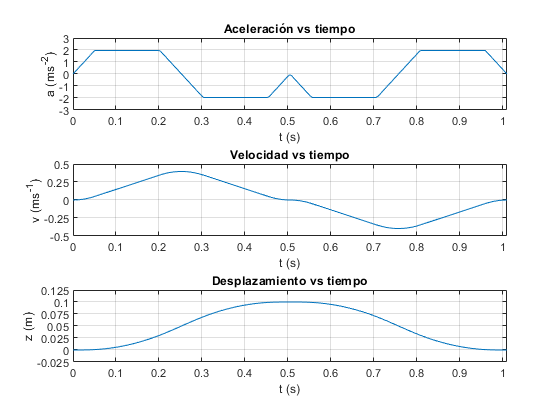

ts=linspace(0,tMax_a,200);

subplot(3,1,1)
plot(ts,a(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (ms^{-2})')
ylim([-3 3])
xlim([0 double(tMax_a)])
yticks(-3:1:3)


subplot(3,1,2)

plot(ts,v(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (ms^{-1})')
%ylim([0 0.7])
xlim([0 double(tMax_a)])
yticks(-0.5:0.25:0.5)

subplot(3,1,3)

plot(ts,Fz_arfada(ts))
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (m)')
ylim([-0.025 0.125])
xlim([0 double(tMax_a)])
yticks(-0.025:0.025:0.125)



clearvars -except prueba tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b L_ub L_bm theta_C beta Z_arfada ArfadaCaso1 ArfadaCaso2 ArfadaCaso3 CabeceoCaso1 CabeceoCaso2 CabeceoCaso3 BalanceoCaso1 BalanceoCaso2 BalanceoCaso3